clear; clc; close all;

%% STEP 1 — LOAD DATASET
filePath = "C:\Users\sreer\OneDrive\Desktop\D12_MFC4_Spectral_Imputation\Dataset_stations\city_day.csv";
T = readtable(filePath);

T.Properties.VariableNames = matlab.lang.makeValidName(T.Properties.VariableNames);


%% STEP 2 — SELECT CITY
cities = unique(T.City);

fprintf('\nAvailable Cities:\n');


Available Cities:


for i = 1:numel(cities)
    fprintf('  [%2d] %s\n', i, cities{i});
end

  [ 1] Ahmedabad
  [ 2] Aizawl
  [ 3] Amaravati
  [ 4] Amritsar
  [ 5] Bengaluru
  [ 6] Bhopal
  [ 7] Brajrajnagar
  [ 8] Chandigarh
  [ 9] Chennai
  [10] Coimbatore
  [11] Delhi
  [12] Ernakulam
  [13] Gurugram
  [14] Guwahati
  [15] Hyderabad
  [16] Jaipur
  [17] Jorapokhar
  [18] Kochi
  [19] Kolkata
  [20] Lucknow
  [21] Mumbai
  [22] Patna
  [23] Shillong
  [24] Talcher
  [25] Thiruvananthapuram
  [26] Visakhapatnam



cityIndex = input(sprintf('\nEnter city number (1 to %d): ', numel(cities)));

if isempty(cityIndex) || cityIndex < 1 || cityIndex > numel(cities)
    error('Invalid city number.');
end

cityName = string(cities{cityIndex});
T = T(strcmp(T.City, cityName), :);

fprintf('\n>> Selected City: %s  (%d rows)\n', cityName, height(T));


>> Selected City: Shillong  (310 rows)




%% STEP 3 — SELECT POLLUTANT
excludeCols  = {'City','Date','Datetime','AQI','AQI_Bucket'};
vars         = T.Properties.VariableNames;
all_features = vars(~ismember(vars, excludeCols));

fprintf('\nAvailable Pollutants for %s:\n', cityName);


Available Pollutants for Shillong:


for i = 1:numel(all_features)
    fprintf('  [%2d] %s\n', i, all_features{i});
end

  [ 1] PM2_5
  [ 2] PM10
  [ 3] NO
  [ 4] NO2
  [ 5] NOx
  [ 6] NH3
  [ 7] CO
  [ 8] SO2
  [ 9] O3
  [10] Benzene
  [11] Toluene
  [12] Xylene


fprintf('  [ 0] ALL pollutants\n');

  [ 0] ALL pollutants



pollutantIndex = input(sprintf('\nEnter pollutant number (0 = all, 1 to %d): ', numel(all_features)));

if isempty(pollutantIndex) || pollutantIndex < 0 || pollutantIndex > numel(all_features)
    error('Invalid pollutant number.');
elseif pollutantIndex == 0
    feature_names = all_features;
    fprintf('\n>> Processing ALL %d pollutants.\n\n', numel(feature_names));
else
    feature_names = all_features(pollutantIndex);
    fprintf('\n>> Selected Pollutant: %s\n\n', feature_names{1});
end


>> Selected Pollutant: NO2



Feature: NO2


  FIR filter applied  (order=20, cutoff=0.10)


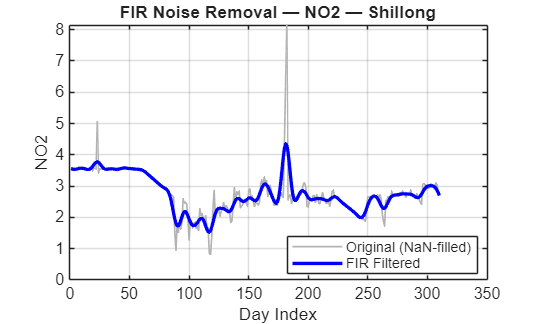

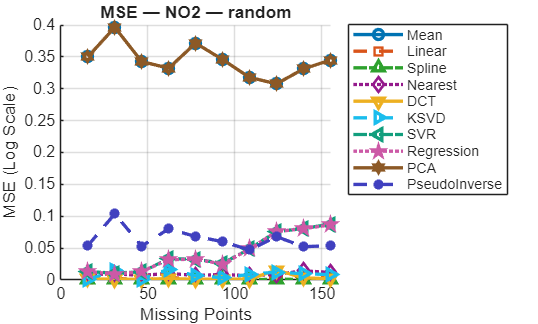

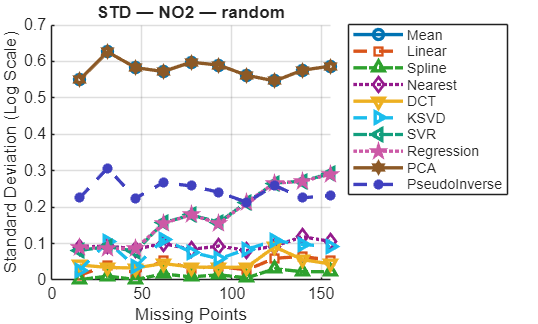

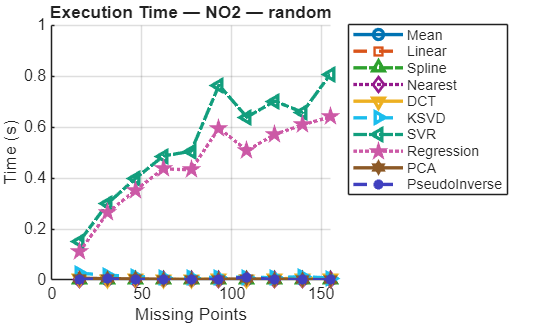

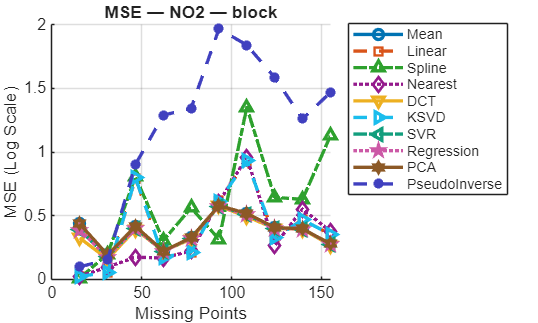

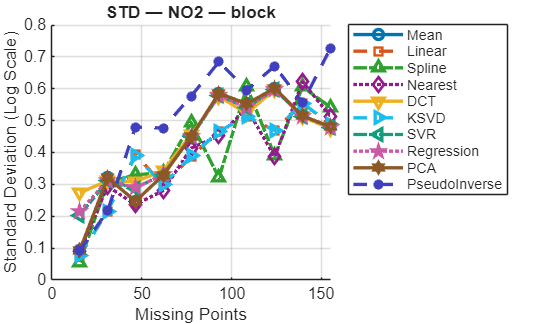

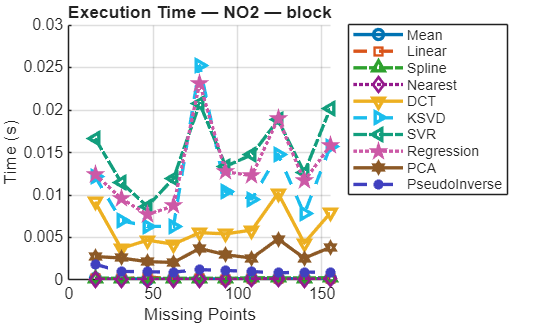



%% =========================================================================
%% FIR FILTER SPECIFICATIONS  (applied to each pollutant before imputation)
%% =========================================================================
% city_day.csv → 1 sample per day
fs        = 1;       % Sampling frequency (samples/day)
f_cutoff  = 0.1;     % Low-pass cutoff (filters noise changing faster than ~10 days)
Wn        = f_cutoff / (fs/2);   % Normalised cutoff  (0 < Wn < 1)
fir_order = 20;
b_fir     = fir1(fir_order, Wn, 'low');
a_fir     = 1;       % FIR → denominator always 1
%% =========================================================================


missing_ratios = 0.05:0.05:0.50;
lossTypes      = {'random','block'};
num_trials     = 3;

% ── 12 methods ────────────────────────────────────────────────────────────
methods = {'Mean','Linear','Spline','Nearest','DCT','KSVD', ...
           'SVR','Regression','PCA','PseudoInverse'};
num_methods = length(methods);

% ── Unique plot style for each of the 12 methods ─────────────────────────
plotColors = [
    0.00  0.45  0.70;   %  1 Mean          – blue
    0.85  0.33  0.10;   %  2 Linear         – burnt-orange
    0.18  0.63  0.18;   %  3 Spline         – green
    0.58  0.10  0.55;   %  4 Nearest        – purple
    0.93  0.69  0.13;   %  5 DCT            – gold
    0.10  0.74  0.93;   %  6 KSVD           – sky-blue
    % 0.70  0.08  0.10;   %  7 Autoencoder    – dark-red
    % 0.00  0.00  0.00;   %  8 EM             – black
    0.07  0.62  0.49;   %  9 SVR            – teal
    0.80  0.35  0.65;   % 10 Regression     – magenta-pink
    0.55  0.35  0.15;   % 11 PCA            – brown
    0.25  0.25  0.75;   % 12 PseudoInverse  – indigo
];
plotStyles  = {'-','--','-.',':','-','--','-.',':','-','--'};
plotMarkers = {'o','s','^','d','v','>','<','p','h','*'};

totalStart = tic;


%% STEP 4 — MAIN LOOP
for f = 1:length(feature_names)

    feature = feature_names{f};
    fprintf('\n============================\n');
    fprintf('Feature: %s\n', feature);
    fprintf('============================\n');

    colData = T.(feature);
    x_raw   = double(colData);

    if all(isnan(x_raw))
        fprintf('  [SKIP] All NaN.\n');
        continue
    end

    % Fill any pre-existing NaNs before filtering (filtfilt needs clean input)
    x_prefilled = fillmissing(x_raw, 'linear');

    N = length(x_prefilled);
    if N < 50
        fprintf('  [SKIP] Too short (%d samples).\n', N);
        continue
    end

    % =====================================================================
    %  FIR FILTERING — applied ONCE per pollutant before imputation
    %  filtfilt gives zero-phase (no time-shift) smoothing
    % =====================================================================
    if N > 3 * fir_order
        x = filtfilt(b_fir, a_fir, x_prefilled);
        fprintf('  FIR filter applied  (order=%d, cutoff=%.2f)\n', fir_order, f_cutoff);
    else
        x = x_prefilled;
        fprintf('  [INFO] Signal too short for FIR — using pre-filled signal.\n');
    end

    % ── Plot: Original vs FIR-filtered ───────────────────────────────────
    figure('Color','w', 'Name', ['FIR Filter — ', feature])
    plot(x_prefilled, 'Color',[0.7 0.7 0.7], 'LineWidth', 1);
    hold on
    plot(x, 'b', 'LineWidth', 2);
    hold off
    legend('Original (NaN-filled)', 'FIR Filtered', 'Location','best')
    grid on
    xlabel('Day Index')
    ylabel(feature)
    title(['FIR Noise Removal — ', feature, ' — ', char(cityName)], 'FontWeight','bold')
    % ─────────────────────────────────────────────────────────────────────

    for lt = 1:length(lossTypes)

        lossType = lossTypes{lt};

        MSE  = zeros(length(missing_ratios), num_methods);
        STD  = zeros(length(missing_ratios), num_methods);
        TIME = zeros(length(missing_ratios), num_methods);

        for r = 1:length(missing_ratios)

            ratio    = missing_ratios(r);
            num_mask = round(ratio * N);

            mse_trials  = zeros(num_trials, num_methods);
            std_trials  = zeros(num_trials, num_methods);
            time_trials = zeros(num_trials, num_methods);

            for t = 1:num_trials

                if strcmp(lossType, 'random')
                    mask_pos = randperm(N, num_mask);
                else
                    start_id = randi([1, N - num_mask + 1]);
                    mask_pos = start_id : start_id + num_mask - 1;
                end

                % Introduce artificial missing values into FIR-filtered signal
                x_test = x;
                x_test(mask_pos) = NaN;

                % Known range — used for clipping spline boundary blow-ups
                x_known_min = min(x_test, [], 'omitnan');
                x_known_max = max(x_test, [], 'omitnan');

                %% 1. Mean
                tic
                x_mean = fillmissing(x_test, 'constant', mean(x_test,'omitnan'));
                time_trials(t,1) = toc;

                %% 2. Linear
                tic
                x_linear = fillmissing(x_test, 'linear');
                time_trials(t,2) = toc;

                %% 3. Spline
                % Clipped to known data range to prevent boundary blow-up MSE
                tic
                x_spline = fillmissing(x_test, 'spline');
                x_spline = max(x_known_min, min(x_known_max, x_spline));
                time_trials(t,3) = toc;

                %% 4. Nearest
                tic
                x_near = fillmissing(x_test, 'nearest');
                time_trials(t,4) = toc;

                %% 5. DCT
                tic
                x_dct = dct_imputation(x_test);
                time_trials(t,5) = toc;

                %% 6. KSVD
                tic
                x_ksvd = ksvd_imputation(x_test);
                time_trials(t,6) = toc;

                % %% 7. Autoencoder
                % tic
                % x_auto = autoencoder_imputation(x_test);
                % time_trials(t,7) = toc;
                % 
                % %% 8. EM
                % tic
                % x_em = em_imputation(x_test);
                % time_trials(t,8) = toc;

                %% 9. SVR
                tic
                x_svr = svr_imputation(x_test);
                time_trials(t,7) = toc;

                %% 10. Regression
                tic
                x_regression = regression_imputation(x_test);
                time_trials(t,8) = toc;

                %% 11. PCA
                tic
                x_pca = pca_imputation(x_test);
                time_trials(t,9) = toc;

                %% 12. Pseudo Inverse
                tic
                x_pinv = pseudoinverse_imputation(x_test);
                time_trials(t,10) = toc;

                recons = {x_mean, x_linear, x_spline, x_near, ...
                          x_dct,  x_ksvd, ...
                          x_svr,  x_regression, x_pca,  x_pinv};

                for m = 1:num_methods
                    err = recons{m}(mask_pos) - x(mask_pos);
                    mse_trials(t,m) = mean(err.^2);
                    std_trials(t,m) = std(err);
                end

            end

            MSE(r,:)  = mean(mse_trials,1);
            STD(r,:)  = mean(std_trials,1);
            TIME(r,:) = mean(time_trials,1);

        end

        %% PLOTS
        xAxis     = missing_ratios * N;
        titleBase = [feature,' — ',lossType];

        % --- MSE ---
        figure('Color','w', 'Name',['MSE — ',titleBase])
        hold on
        for mi = 1:num_methods
            semilogy(xAxis, MSE(:,mi), ...
                'Color',      plotColors(mi,:), ...
                'LineStyle',  plotStyles{mi},   ...
                'Marker',     plotMarkers{mi},  ...
                'LineWidth',  2, 'MarkerSize', 6);
        end
        hold off
        legend(methods, 'Location','northeastoutside')
        grid on
        xlabel('Missing Points')
        ylabel('MSE (Log Scale)')
        title(['MSE — ', titleBase], 'FontWeight','bold')

        % --- STD ---
        figure('Color','w', 'Name',['STD — ',titleBase])
        hold on
        for mi = 1:num_methods
            semilogy(xAxis, STD(:,mi), ...
                'Color',      plotColors(mi,:), ...
                'LineStyle',  plotStyles{mi},   ...
                'Marker',     plotMarkers{mi},  ...
                'LineWidth',  2, 'MarkerSize', 6);
        end
        hold off
        legend(methods, 'Location','northeastoutside')
        grid on
        xlabel('Missing Points')
        ylabel('Standard Deviation (Log Scale)')
        title(['STD — ', titleBase], 'FontWeight','bold')

        % --- Execution Time ---
        figure('Color','w', 'Name',['Time — ',titleBase])
        hold on
        for mi = 1:num_methods
            plot(xAxis, TIME(:,mi), ...
                'Color',      plotColors(mi,:), ...
                'LineStyle',  plotStyles{mi},   ...
                'Marker',     plotMarkers{mi},  ...
                'LineWidth',  2, 'MarkerSize', 6);
        end
        hold off
        legend(methods, 'Location','northeastoutside')
        grid on
        xlabel('Missing Points')
        ylabel('Time (s)')
        title(['Execution Time — ', titleBase], 'FontWeight','bold')

    end
end


fprintf('\nTotal elapsed time: %.2f s\n', toc(totalStart));


Total elapsed time: 35.09 s



avg_time = mean(TIME,1)

avg_time =     0.0001    0.0002    0.0002    0.0001    0.0061    0.0115    0.0149    0.0133    0.0030    0.0011




%% =========================================================================
%%  HELPER FUNCTIONS
%% =========================================================================

%% DCT IMPUTATION
function x_hat = dct_imputation(x)

keep_ratio = 0.2;
maxIter    = 30;
tol        = 1e-4;

x     = x(:);
known = ~isnan(x);

x_fill = x;
x_fill(~known) = mean(x(known));

n   = length(x);
thr = round(keep_ratio * n);

for i = 1:maxIter
    prev = x_fill;
    X    = dct(x_fill);
    X(thr+1:end) = 0;
    x_rec = idct(X);
    x_fill(~known) = x_rec(~known);
    if norm(x_fill - prev) / (norm(prev) + 1e-10) < tol
        break
    end
end

x_hat = x_fill;
end


%% FAST K-SVD IMPUTATION
function x_hat = ksvd_imputation(x)

patchSize = 8;
K         = 16;
sparsity  = 2;
maxIter   = 5;

x = x(:);
N = length(x);

known       = ~isnan(x);
x_fill      = x;
idx_known   = find(known);
idx_unknown = find(~known);

if ~isempty(idx_unknown)
    x_fill(idx_unknown) = interp1(idx_known, x(known), idx_unknown, 'linear', 'extrap');
end

D = zeros(patchSize, K);
for k = 1:K
    atom   = cos((0:patchSize-1)' * (k-1) * pi / K);
    D(:,k) = atom / norm(atom);
end

numPatches = N - patchSize + 1;
idx_mat    = bsxfun(@plus, (1:patchSize)', 0:numPatches-1);
Y          = x_fill(idx_mat);

for iter = 1:maxIter

    X_coef = D \ Y;
    [~, sort_idx] = sort(abs(X_coef), 1, 'descend');
    for j = 1:numPatches
        X_coef(sort_idx(sparsity+1:end, j), j) = 0;
    end

    Y_res = Y - D * X_coef;
    for k = 1:K
        used = X_coef(k,:) ~= 0;
        if ~any(used), continue; end
        E_k            = Y_res(:,used) + D(:,k) * X_coef(k,used);
        u              = E_k * X_coef(k,used)';
        d_new          = u / (norm(u) + 1e-10);
        D(:,k)         = d_new;
        X_coef(k,used) = (E_k' * d_new)';
        Y_res(:,used)  = E_k - d_new * X_coef(k,used);
    end

    Y_rec   = D * X_coef;
    weights = accumarray(idx_mat(:), ones(numel(idx_mat),1), [N,1]);
    x_rec   = accumarray(idx_mat(:), Y_rec(:),               [N,1]);
    x_rec   = x_rec ./ max(weights, 1);
    x_fill(~known) = x_rec(~known);
    Y = x_fill(idx_mat);
end

x_hat = x_fill;
end



%% SVR IMPUTATION
function x_hat = svr_imputation(x)

x      = x(:);
N      = length(x);
x_fill = x;

known   = find(~isnan(x));
unknown = find(isnan(x));

for i = unknown'
    if i > 2 && i < N-2
        idx = [i-2, i-1, i+1, i+2];
        idx = idx(~isnan(x(idx)));
        if length(idx) >= 2
            mdl       = fitrsvm(idx', x(idx), 'KernelFunction','gaussian');
            x_fill(i) = predict(mdl, i);
        else
            x_fill(i) = mean(x(known));
        end
    else
        x_fill(i) = mean(x(known));
    end
end

x_hat = x_fill;
end


%% REGRESSION IMPUTATION
function x_hat = regression_imputation(x)

x      = x(:);
N      = length(x);
x_fill = x;

known   = find(~isnan(x));
unknown = find(isnan(x));

for i = unknown'
    if i > 2 && i < N-2
        idx = [i-2, i-1, i+1, i+2];
        idx = idx(~isnan(x(idx)));
        if length(idx) >= 2
            mdl       = fitlm(idx', x(idx));
            x_fill(i) = predict(mdl, i);
        else
            x_fill(i) = mean(x(known));
        end
    else
        x_fill(i) = mean(x(known));
    end
end

x_hat = x_fill;
end


%% PCA IMPUTATION
function x_hat = pca_imputation(x)

x     = x(:);
known = ~isnan(x);
mu    = mean(x(known));

x_fill = x;
x_fill(~known) = mu;

for i = 1:10
    [coeff, score, ~, ~, ~, mu_pca] = pca(x_fill);
    x_rec = (score * coeff') + mu_pca;
    x_fill(~known) = x_rec(~known);
    x_fill(known)  = x(known);   % always preserve known values
end

x_hat = x_fill;
end


%% PSEUDO INVERSE IMPUTATION
function x_hat = pseudoinverse_imputation(x)

x     = x(:);
N     = length(x);
known = ~isnan(x);

% Guard: nothing missing
if all(known)
    x_hat = x;
    return;
end

% Guard: too few known points → fall back to mean
n_known = sum(known);
if n_known < 3
    x_fill         = x;
    x_fill(~known) = mean(x(known));
    x_hat          = x_fill;
    return;
end

% ── 1. Normalise time index to [-1, 1] for numerical stability ───────────
t      = (1:N)' / N;
t_norm = 2*t - 1;

t_known   = t_norm( known);
t_missing = t_norm(~known);
x_known   = x(known);

% ── 2. Adaptive polynomial order ─────────────────────────────────────────
%  p = min(floor(sqrt(n_known)), 20), at least cubic
p_max = min(floor(sqrt(n_known)), 20);
p     = max(p_max, 3);

% ── 3. Build Vandermonde basis matrices ──────────────────────────────────
Phi_known   = vandermonde_basis(t_known,   p);   % n_known   × (p+1)
Phi_missing = vandermonde_basis(t_missing, p);   % n_missing × (p+1)

% ── 4. Solve via pseudo-inverse (SVD-based, robust to near-singular) ─────
c_hat = pinv(Phi_known) * x_known;

% ── 5. Recover missing values ─────────────────────────────────────────────
x_miss_rec = Phi_missing * c_hat;

% ── 6. Assemble output & clip to observed range ──────────────────────────
x_hat         = x;
x_hat(~known) = x_miss_rec;

lo = min(x_known);
hi = max(x_known);
x_hat(~known) = max(lo, min(hi, x_hat(~known)));

end


%% VANDERMONDE BASIS  (helper for pseudoinverse_imputation)
%  Returns matrix of size (length(t) x (p+1)):
%    columns are  t.^0, t.^1, t.^2, ..., t.^p
function Phi = vandermonde_basis(t, p)
t   = t(:);
Phi = t .^ (0:p);
end